f = imread("eye.PNG");
f = rgb2gray(f)

f = 108×112 uint8 matrix
    66    66    62    66    62    56    60    60    62    67    73    77    83    87    82    79    84    86    89    97    98    94   112   125   123   116   106   109   115   102    83    82    97   103    93    85    90   100   117   127   138   144   138   126   121   118   116   119   126   128
    67    70    64    65    61    54    57    56    57    69    74    78    82    87    82    79    82    81    90    96    88    92   116   121   111   107   106   108   104    84    73    87   102    96    86    83    89   102   118   131   139   143   134   117   109   107   106   109   116   118
    73    74    66    65    61    55    58    57    59    66    73    77    82    87    82    76    77    79    91    95    82    95   115   112   101   107   114   111    94    73    71    92    96    84    80    84    92   104   114   123   130   133   122   106    98    93    92    95    95   100
    75    76    68    66    63    58    60    60    64    66    73    76

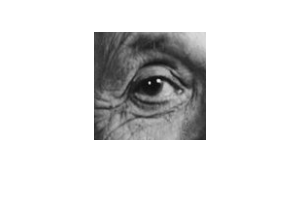

imshow(f);

filt = [0 0 0 ; 0 1 0; 0 0 0];

filt =      0     0     0
     0     1     0
     0     0     0


imfilter(f,filt)

ans = 108×112 uint8 matrix
    66    66    62    66    62    56    60    60    62    67    73    77    83    87    82    79    84    86    89    97    98    94   112   125   123   116   106   109   115   102    83    82    97   103    93    85    90   100   117   127   138   144   138   126   121   118   116   119   126   128
    67    70    64    65    61    54    57    56    57    69    74    78    82    87    82    79    82    81    90    96    88    92   116   121   111   107   106   108   104    84    73    87   102    96    86    83    89   102   118   131   139   143   134   117   109   107   106   109   116   118
    73    74    66    65    61    55    58    57    59    66    73    77    82    87    82    76    77    79    91    95    82    95   115   112   101   107   114   111    94    73    71    92    96    84    80    84    92   104   114   123   130   133   122   106    98    93    92    95    95   100
    75    76    68    66    63    58    60    60    64    66    73    

Shifting to the left

filt = [0 0 0 ; 0 0 1; 0 0 0];
out = imfilter(f,filt)

out = 108×112 uint8 matrix
    66    62    66    62    56    60    60    62    67    73    77    83    87    82    79    84    86    89    97    98    94   112   125   123   116   106   109   115   102    83    82    97   103    93    85    90   100   117   127   138   144   138   126   121   118   116   119   126   128   134
    70    64    65    61    54    57    56    57    69    74    78    82    87    82    79    82    81    90    96    88    92   116   121   111   107   106   108   104    84    73    87   102    96    86    83    89   102   118   131   139   143   134   117   109   107   106   109   116   118   123
    74    66    65    61    55    58    57    59    66    73    77    82    87    82    76    77    79    91    95    82    95   115   112   101   107   114   111    94    73    71    92    96    84    80    84    92   104   114   123   130   133   122   106    98    93    92    95    95   100   108
    76    68    66    63    58    60    60    64    66    73    76    

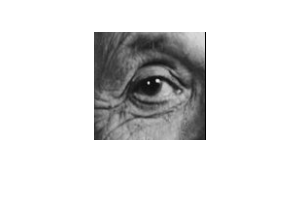

imshow(out);

Sharpening image

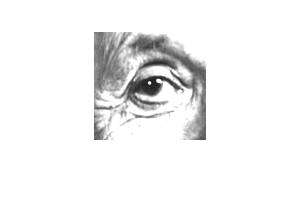

filt = [0 0 0 ; 0 2 0; 0 0 0] - [1 1 1 ; 1 1 1; 1 1 1]./9;
filt1  =[1 1 1 ; 1 1 1; 1 1 1]./9;
filt2 = [0 0 0 ; 0 2 0; 0 0 0];
out1 = imfilter(f,filt2);
out2 = imfilter(f,filt1);
imshow(out1);

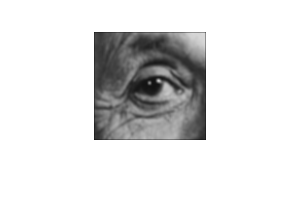

imshow(out2);

filt3 = filt2 - filt1

filt3 =    -0.1111   -0.1111   -0.1111
   -0.1111    1.8889   -0.1111
   -0.1111   -0.1111   -0.1111


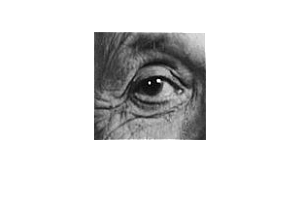

out = imfilter(f,filt3);
imshow(out)